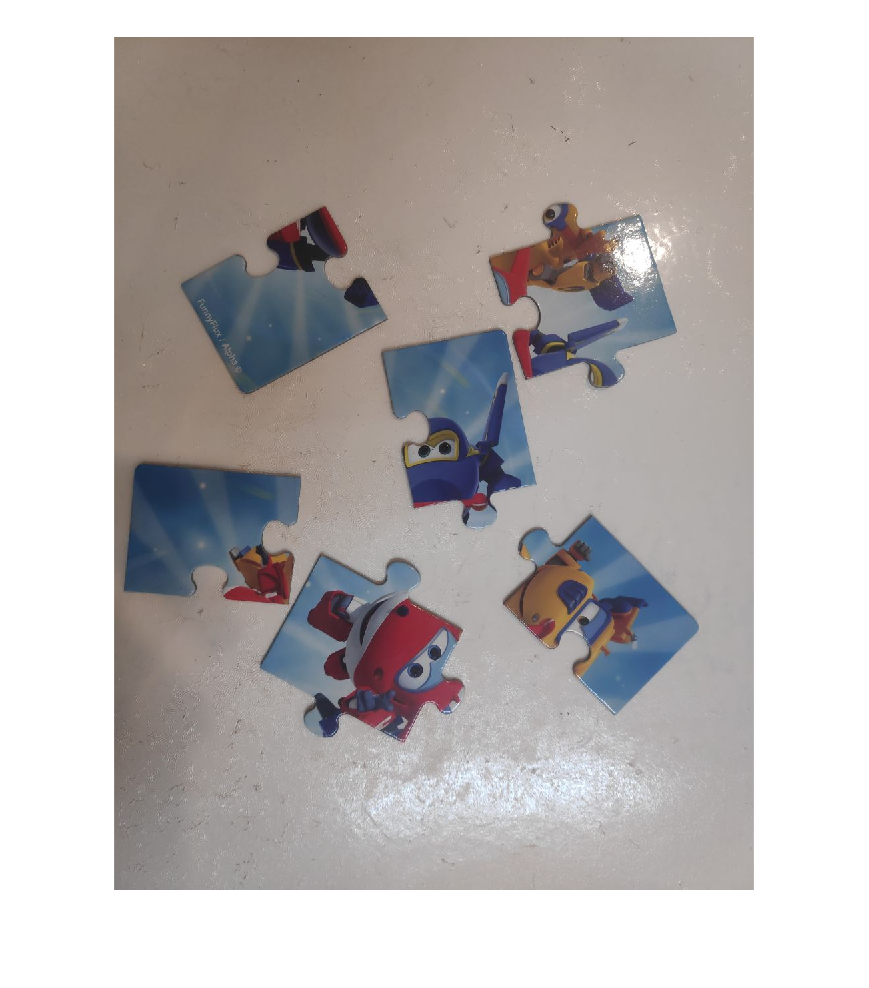

RGB=imread("..\img\pzl_6_2.jpg");
imshow(RGB)

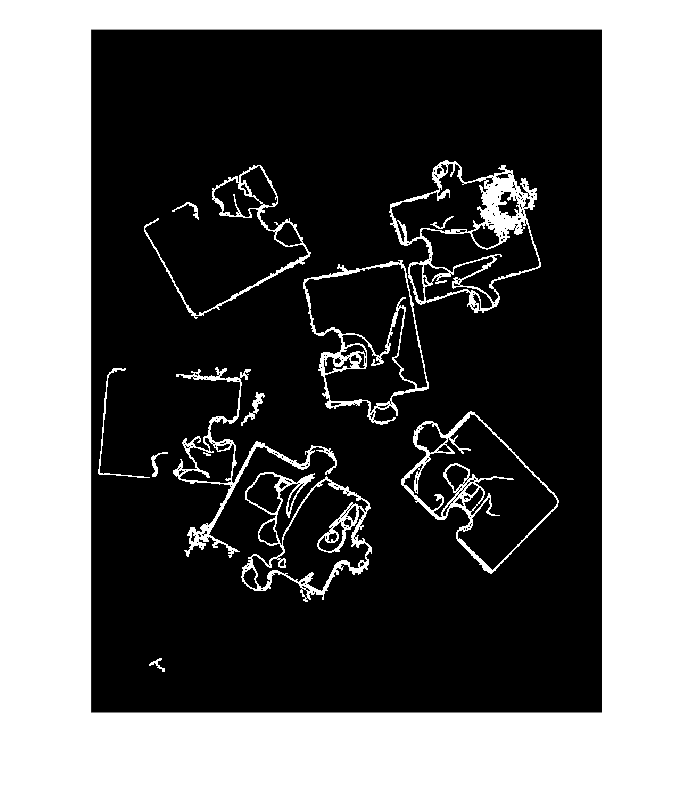

% RGB = imread('kobi.png');
% RGB=imresize(RGB,0.1);

img=dip_GN_imread("..\img\pzl_6_2.jpg");
BW=edge(img,"prewitt");
% imshow(imclose(BW,strel("rectangle",[2,2])));

dial = imdilate(BW,strel("rectangle",[3,3]));
solidity = bwpropfilt(dial, 'Solidity', [0, 0.5]);
extent = bwpropfilt(dial, 'Extent', [0, 0.3]);
% imshow(BW);
% imshow(dial);
% imshow(solidity);
imshow(extent);

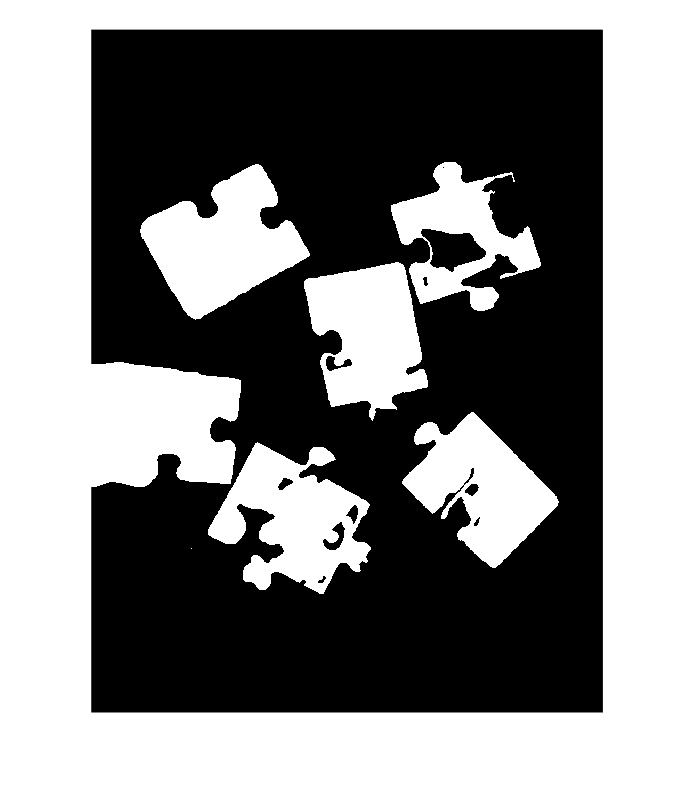

% imshow(imfill(extent,"holes"));
% imshow(imfill(imfill(solidity,'holes'),"holes"));
I = im2gray(im2single(RGB));
evolved = activecontour(I,extent,600,"Chan-vese","ContractionBias",-0.1,"SmoothFactor",0.6);
filled = imfill(evolved,"holes");
imshow(evolved);

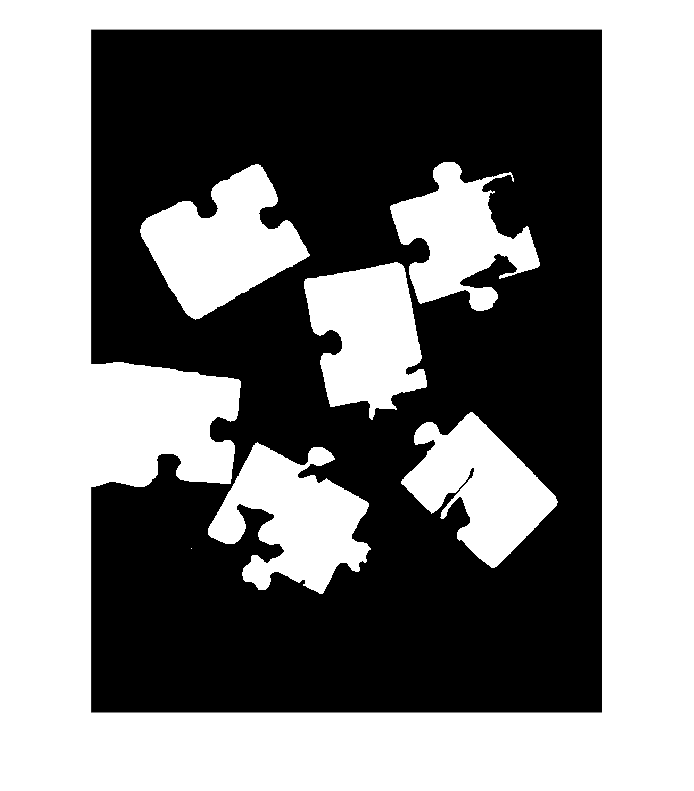

imshow(filled);

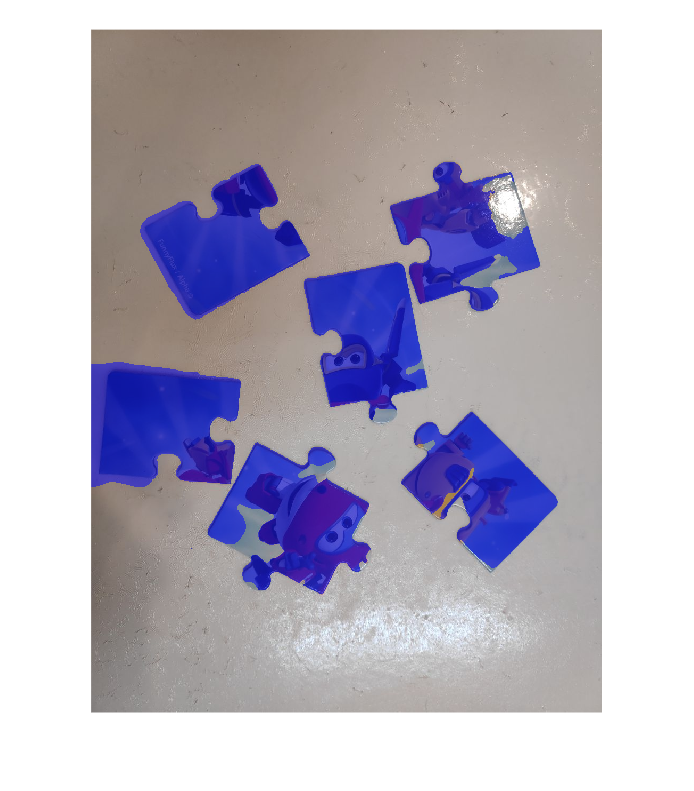

C = labeloverlay(RGB,filled);
imshow(C)

% nrows = size(RGB,1);
% ncols = size(RGB,2);
% [X,Y] = meshgrid(1:ncols,1:nrows);
% I = im2gray(im2single(RGB));
% imshow(I);
% imshow(I-extent*0.5);
% featureSet = cat(3,I,X,Y,extent);
% uint8(V*255)
% L2 = imsegkmeans(I-extent*0.5,2,'NormalizeInput',true);
% C = labeloverlay(RGB,imfill(L2,"holes"));
% imshow(C)

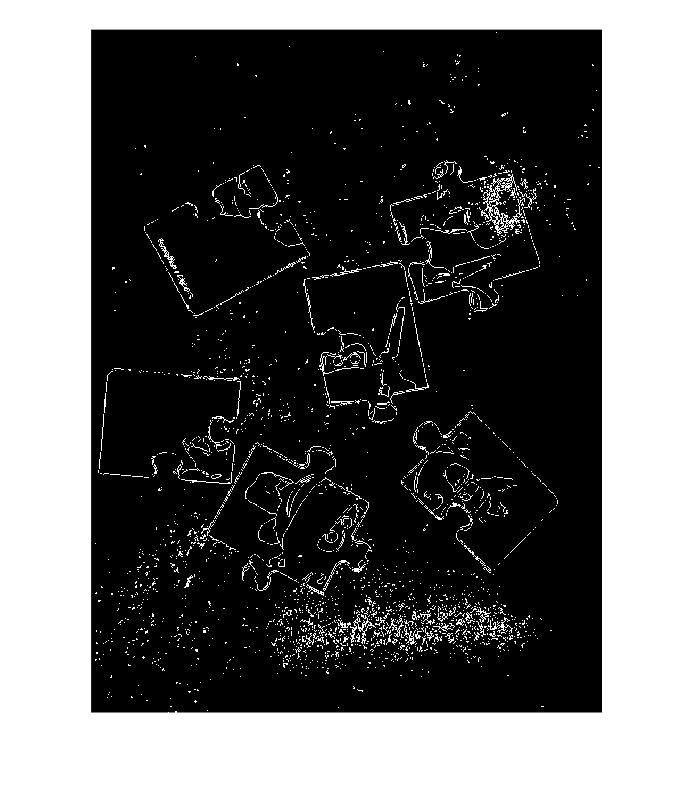

thresh = uint8(3);
thresh2 = uint8(3);
a=fill_black(BW,2,thresh);
b = fill_white(a,3,thresh2);
imshow(a);

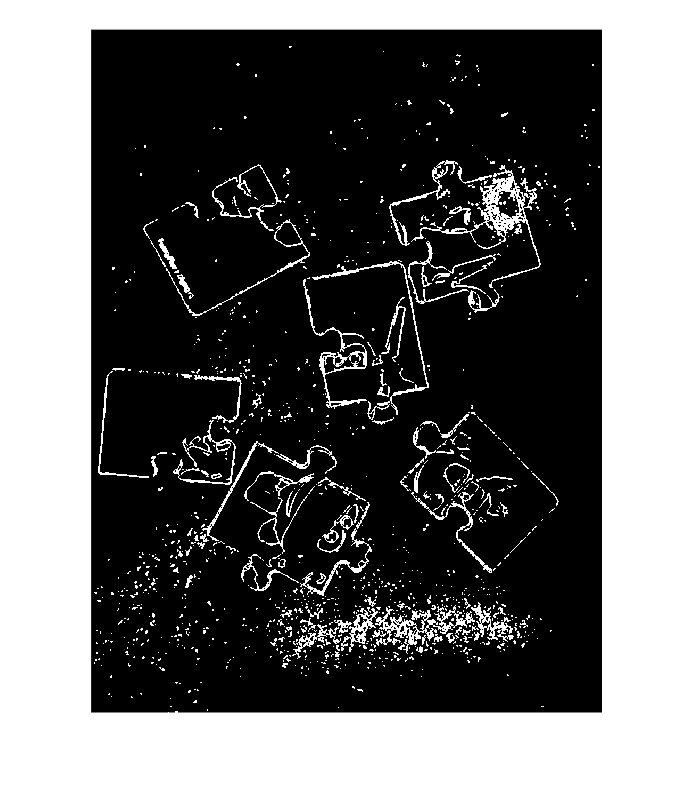

imshow(b);

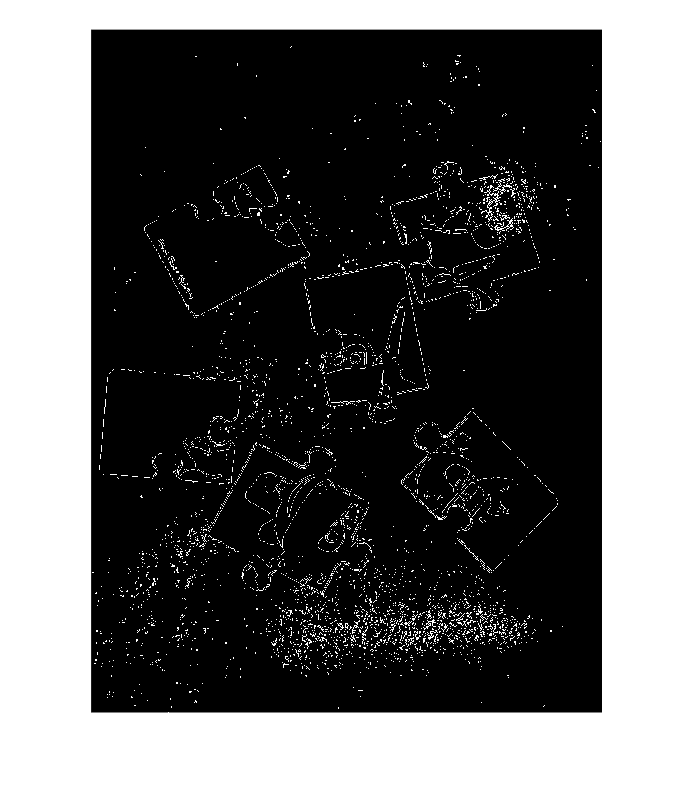

imshow(BW);


% [H, S ,V]=rgb2hsv(RGB);
% S=uint8(S);
% L = imsegkmeans(S,2);
% B = labeloverlay(S,L);
% imshow(B)
% title('Labeled Image')



% wavelength = 2.^(0:5) * 3;
% orientation = 0:45:135;
% g = gabor(wavelength,orientation);
% 
% I = im2gray(im2single(RGB));
% gabormag = imgaborfilt(I,g);

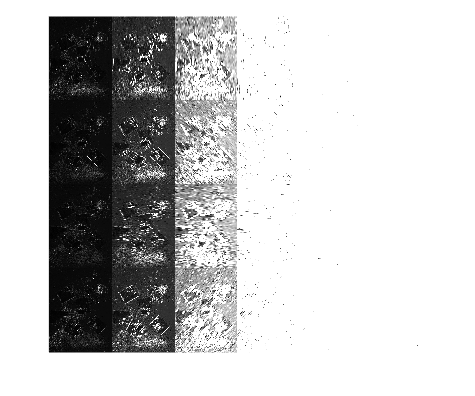

montage(gabormag,'Size',[4 6])

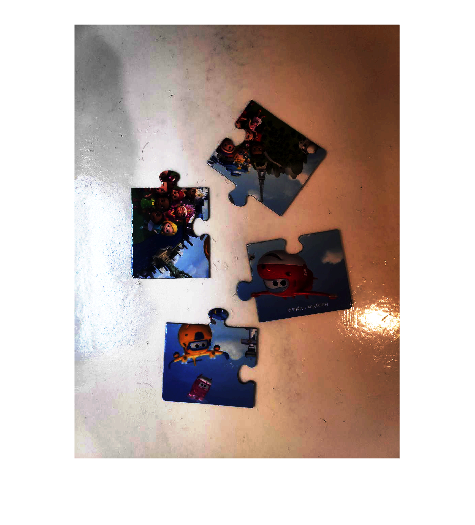

nrows = size(RGB,1);
ncols = size(RGB,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
% featureSet = cat(3,I,gabormag,X,Y,BW);
RGB=imread("..\img\pzl_4_2.jpg");
contrasted = histeq(RGB,64);
imshow(contrasted);

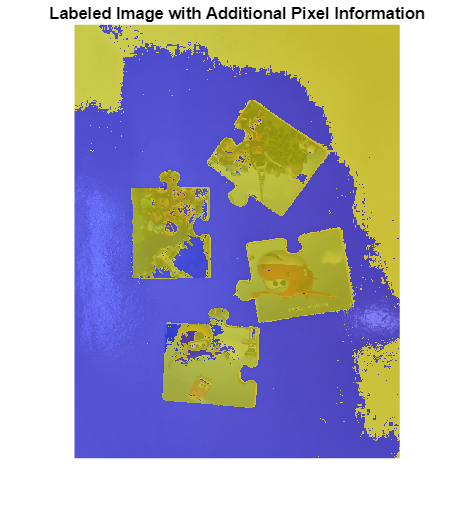

[H, S ,V]=rgb2hsv(contrasted);
featureSet = cat(3,uint8(V*255),uint8(H*255));
% uint8(V*255)
L2 = imsegkmeans(uint8(V*255),2,'NormalizeInput',true);
C = labeloverlay(RGB,L2);
imshow(C)
title('Labeled Image with Additional Pixel Information')

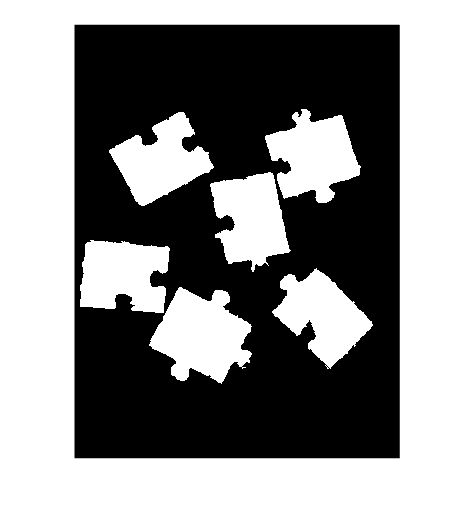

RGB=imread("..\img\pzl_6_2.jpg");
imshow(autosegmentImage(RGB));